clc;clear;

l1 = 203;
l2 = 178;
l3 = 178;

phi1_min = -90;
phi1_max = 90;
phi2_min = -55;
phi2_max = 125;
phi3_min = 0;
phi3_max = 150;

phi1 =21;
phi2 =45;
phi3 =30;

krok = 5;

% cs for CoordinateSystem
cs.i(:,1) = [50; 0; 0; 1];
cs.j(:,1) = [0; 50; 0; 1];
cs.k(:,1) = [0; 0; 50; 1];
bod(:,1) = [0; 0; 0; 1];

Rotácia R1z

cs.i(:,2) = (rob_rotate('z','deg',phi1)*cs.i(:,1));
cs.j(:,2) = (rob_rotate('z','deg',phi1)*cs.j(:,1));
cs.k(:,2) = (rob_rotate('z','deg',phi1)*cs.k(:,1));

Translácia T2z

bod(:,2) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*bod(:,1));
cs.i(:,3) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*cs.i(:,1));
cs.j(:,3) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*cs.j(:,1));
cs.k(:,3) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*cs.k(:,1));

Rotácia R3y

cs.i(:,4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*cs.i(:,1));
cs.j(:,4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*cs.j(:,1));
cs.k(:,4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*cs.k(:,1));

Translácia T4z

bod(:,3) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*bod(:,1));
cs.i(:,5) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*cs.i(:,1));
cs.j(:,5) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*cs.j(:,1));
cs.k(:,5) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*cs.k(:,1));

Rotácia R5y

cs.i(:,6) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*cs.i(:,1));
cs.j(:,6) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*cs.j(:,1));
cs.k(:,6) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*cs.k(:,1));

Translácia T6z

bod(:,4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
cs.i(:,7) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*cs.i(:,1));
cs.j(:,7) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*cs.j(:,1));
cs.k(:,7) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*cs.k(:,1));

Výpočet prac. priestoru xy

xy_iter = 1;

xy = zeros(5,360/krok);

for (i = 0:krok:360)
    xy(:,xy_iter) = [0;0;l1;0;i];
    xy_iter = xy_iter + 1;
end

for(phi1 = phi1_min:krok:phi1_max)
    for(phi2 = phi2_min:krok:phi2_max)
        for(phi3 = phi3_min:krok:phi3_max)
            Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
            Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));
            Ct(6) = atan2(Ct(2),Ct(1));
            Ct(6) = round(rad2deg(Ct(6)),0);
            if Ct(6) < 0
                Ct(6) = Ct(6) + 360;
            end

            I = find(xy(5,:) == Ct(6));

            if(xy(4,I) < Ct(5))
                xy(:,I) = [Ct(1);Ct(2);l1;Ct(5);Ct(6)];
            end 
        end
    end
end
xy(1:4,end) = xy(1:4,1);

if(phi1_max+abs(phi1_min) >= 180)
    for (uhol = [phi1_min,phi1_max])
        uhol = mod(uhol, 360);
        I = find(xy(5,:) == uhol);
        val = xy(:,I-1:I+1);

        [M,Is] = min(val(4,:));
        smallest = val(:,Is);
        [M,Im] = max(val(4,:));
        biggest = val(:,Im);

        x = smallest(4)*cos(deg2rad(uhol));
        y = smallest(4)*sin(deg2rad(uhol));

        valIn = [x;y;l1;smallest(4);val(5,2)];
        
        if(xy(4,I-1) < xy(4,I))
            xy = [xy(:,1:I-1), valIn, xy(:,I:end)];
        else
            xy = [xy(:,1:I), valIn, xy(:,I+1:end)];
        end
    end
end

Výpočet prac. priestoru xz

xz_iter = 1;
krok = 5;

phi1 = 0;
phi2 = phi2_min;

for(phi3 = phi3_min:krok:phi3_max)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

phi3 = phi3_max;

for(phi2 = phi2_min:krok:phi2_max)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

phi2 = phi2_max;

for(phi3 = phi3_max:-krok:phi3_min)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

phi3 = phi3_min;

for(phi2 = phi2_max:-krok:phi2_min)
    Ct(1:4) = (rob_rotate('z','deg',phi1)*rob_translate('z',l1)*rob_rotate('y','deg',phi2)*rob_translate('z',l2)*rob_rotate('y','deg',phi3)*rob_translate('z',l3)*bod(:,1));
    Ct(5) = sqrt(Ct(1)*Ct(1)+Ct(2)*Ct(2));

    xz(1:3,xz_iter) = Ct(1:3);
    xz(4,xz_iter) = Ct(5);

    xz_iter = xz_iter + 1;
end

# Vykreslenie údajov

figure; hold on; grid on;
axis equal;
xlim([-400 400]);
ylim([-400 400]);
zlim([-100 600]);
view([40 30])
xlabel('x');
ylabel('y');
zlabel('z');

Vykreslenie ramien 0-A, A-B, B-C

for (iterator = 2:1:length(bod))
    rob_plot3(bod(:,iterator-1),bod(:,iterator))
    rob_sphere(7,bod(:,iterator))
end

Súr.Sys 0

plot3([bod(1,1),cs.i(1,2)],[bod(2,1),cs.i(2,2)],[bod(3,1),cs.i(3,2)],'Color','red','LineWidth',2)
plot3([bod(1,1),cs.j(1,2)],[bod(2,1),cs.j(2,2)],[bod(3,1),cs.j(3,2)],'Color','green','LineWidth',2)
plot3([bod(1,1),cs.k(1,2)],[bod(2,1),cs.k(2,2)],[bod(3,1),cs.k(3,2)],'Color','blue','LineWidth',2)

Súr.Sys A

plot3([bod(1,2),cs.i(1,3)],[bod(2,2),cs.i(2,3)],[bod(3,2),cs.i(3,3)],'Color','red','LineWidth',2)
plot3([bod(1,2),cs.j(1,3)],[bod(2,2),cs.j(2,3)],[bod(3,2),cs.j(3,3)],'Color','green','LineWidth',2)
plot3([bod(1,2),cs.k(1,3)],[bod(2,2),cs.k(2,3)],[bod(3,2),cs.k(3,3)],'Color','blue','LineWidth',2)

Súr.Sys B

plot3([bod(1,3),cs.i(1,5)],[bod(2,3),cs.i(2,5)],[bod(3,3),cs.i(3,5)],'Color','red','LineWidth',2)
plot3([bod(1,3),cs.j(1,5)],[bod(2,3),cs.j(2,5)],[bod(3,3),cs.j(3,5)],'Color','green','LineWidth',2)
plot3([bod(1,3),cs.k(1,5)],[bod(2,3),cs.k(2,5)],[bod(3,3),cs.k(3,5)],'Color','blue','LineWidth',2)

Súr.Sys C

plot3([bod(1,4),cs.i(1,7)],[bod(2,4),cs.i(2,7)],[bod(3,4),cs.i(3,7)],'Color','red','LineWidth',2)
plot3([bod(1,4),cs.j(1,7)],[bod(2,4),cs.j(2,7)],[bod(3,4),cs.j(3,7)],'Color','green','LineWidth',2)
plot3([bod(1,4),cs.k(1,7)],[bod(2,4),cs.k(2,7)],[bod(3,4),cs.k(3,7)],'Color','blue','LineWidth',2)

XY - prac. priestor

fill3(xy(1,:),xy(2,:),xy(3,:),'r','EdgeColor','none','FaceColor','red','FaceAlpha','0.2');
plot3(xy(1,:),xy(2,:),xy(3,:),'Color','red','LineWidth',2);

ABC - prac. priestor

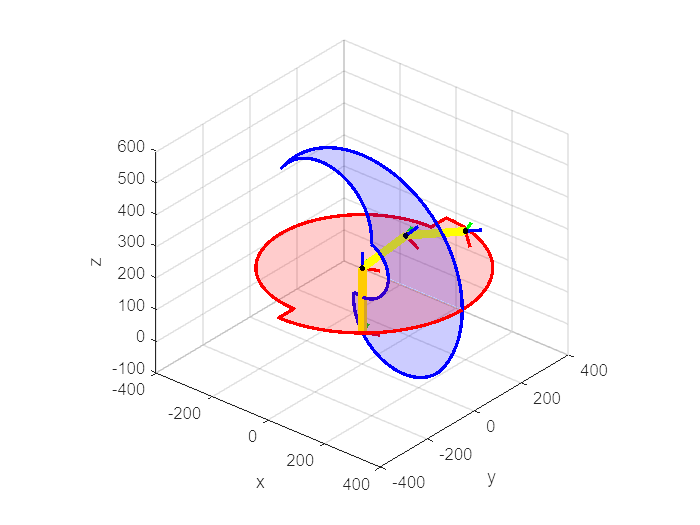

fill3(xz(1,:),xz(2,:),xz(3,:),'b','EdgeColor','none','FaceColor','blue','FaceAlpha','0.2');
plot3(xz(1,:),xz(2,:),xz(3,:),'Color','blue','LineWidth',2);